# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

Usar EDO45 para resolver uma edo

- a ideia é ter um sistema de edos de 1ª ordem

- Resolver um PVI

Intervalo de solução:

t0=0;
t1=30;

Parâmetros do sistema de equações:

V=[6./5, 3./5; 4./5, 0];
V(2,2)=V(1,2)/2;

Condições iniciais:

CI_t0=[2 1];

Retorna:

- Intervalo de tempo em que a função foi achada (linspace)

- retorna uma matriz com as entradas em coluna dos valores da função para cada tempo

[t,y] = ode45(@(t,y) sist_edo(t,y,V),[t0,t1],CI_t0);

Plot dos gráficos:

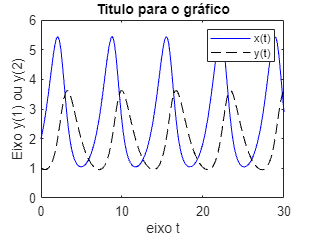

figure(1)
plot(t,y(:,1),'blue-')
hold on
plot(t,y(:,2),'black--')
title('Titulo para o gráfico')
xlabel('eixo t');
ylabel('Eixo y(1) ou y(2)');
legend('x(t)','y(t)'); 

Função com a EDO em forma de matriz (que nem era em mat-32):

function fxy = sist_edo(t,y,V)

fxy=[V(1,1)*y(1) - V(1,2)*y(1)*y(2);(-1)*V(2,1)*y(2) + V(2,2)*y(1)*y(2)];

end